# 4주차 — 시간응답: 성능을 숫자로 적기

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

지금까지 "빠르다", "진동한다" 를 **감으로** 말해 왔습니다. 이번 주에는 이것을 **숫자로** 적는 법을 배웁니다.

오늘의 목표

- 응답을 숫자 네 개(상승시간·오버슈트·첨두시간·정착시간)로 요약한다

- 그 숫자와 극점 위치를 잇는 **두 개의 공식**을 익힌다

- 사양을 $s$ 평면의 **영역**으로 그린다

마지막 것이 6주차 설계의 출발점입니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-00. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W04_TimeResponse` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0-0. 오늘 한 장 요약

오늘 하는 일은 **말을 숫자로, 숫자를 위치로** 바꾸는 것입니다.


$$\text{"빠르고 안정적으로"} \;\rightarrow\; \%OS,\; t_s \;\rightarrow\; \zeta,\; \omega_n \;\rightarrow\; s \text{ 평면의 극점}$$


오늘의 계단

- **1~3절** 성능을 나타내는 네 숫자, 1차와 2차 시스템의 응답

- **4절** 오늘의 핵심. 사양과 극점을 잇는 **공식 두 개**

- **5절** 사양을 $s$ 평면의 **영역**으로 그리기 (6주차 설계의 바탕)

- **6절** 공식이 언제 안 맞는가 (극점이 셋 이상일 때)

오늘 딱 하나만 기억한다면 이것입니다.

- **사양은 **$s$** 평면 위의 영역이다.** 설계란 극점을 그 영역 안에 넣는 일이다

오늘 배우는 것을 **한 줄로 이으면** 이렇게 됩니다. 이 그림의 화살표를 왼쪽에서 오른쪽으로 따라가는 것이 4주차 전부입니다.

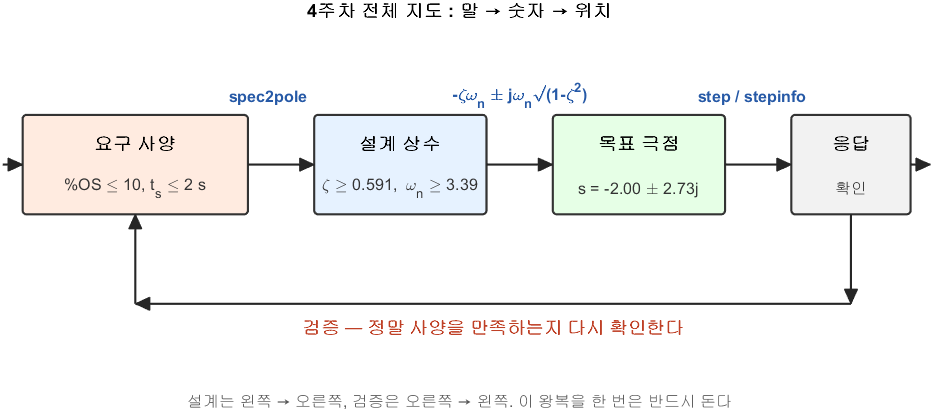

말 → 숫자 → 위치 → 응답, 그리고 되돌아와 확인

**그림 파일** `w04_spec_map.png` — `common/dg_spec_map.m` 의 `dg_spec_map` · 다시 만들려면 `make_figures('w04_spec_map')`

**만드는 곳** — `common/dg_spec_map.m` (`make_figures('w04_spec_map')`) **직접 밟아 보려면** — `W04_02_spec_region.m` 을 처음부터 끝까지 실행하면 이 지도를 그대로 따라갑니다

그림 해석

6주차부터는 셋째 칸(목표 극점)에 도달하는 방법이 **근궤적**으로 바뀝니다. 앞뒤 칸은 그대로입니다.

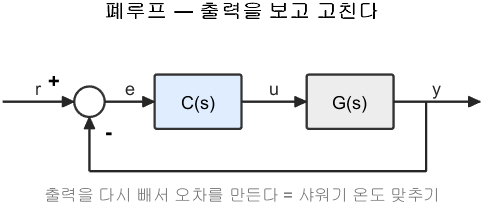

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('closed', ...)` 로 부릅니다

그림 해석

## 0-0-1. 가장 작은 예부터

이해를 돕기 위해 제일 쉬운 것부터 봅니다. 극점 두 개가 어디 있느냐에 따라 응답이 이렇게 달라집니다.

figure;
tiledlayout(1,2,'TileSpacing','compact');
cases = { '천천히, 안 튄다', 0.9, 1
          '적당히',           0.5, 2
          '빠르지만 많이 튄다', 0.2, 3 };
nexttile
hold on; grid on;
for i = 1:3
    z = cases{i,2}; w = cases{i,3};
    pl = pole(w^2/(s^2 + 2*z*w*s + w^2));
    plot(real(pl), imag(pl), 'x', 'MarkerSize', 12, 'LineWidth', 2, ...
         'DisplayName', cases{i,1});
end
xline(0,'k-','HandleVisibility','off'); yline(0,'k-','HandleVisibility','off');
xlabel('실수부'); ylabel('허수부');
title('극점이 여기 있으면');
legend('Location','best');
nexttile
t0 = (0:0.02:12)';
hold on; grid on;
for i = 1:3
    z = cases{i,2}; w = cases{i,3};
    plot(t0, step(w^2/(s^2 + 2*z*w*s + w^2), t0), 'LineWidth', 2, ...
         'DisplayName', cases{i,1});
end
yline(1,'k--','HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력');
title('응답은 이렇게 나온다');
legend('Location','southeast');

이 그림에서 오늘 배울 것이 다 보입니다.

- **왼쪽으로 갈수록** 빨라진다 (실수부가 정착시간을 정한다)

- **위아래로 벌어질수록** 많이 튄다 (각도가 오버슈트를 정한다)

이 두 문장을 식으로 정확히 적는 것이 오늘의 목표입니다.

## 0. 왜 숫자로 적어야 하는가

"이 제어기가 좋습니다" 라고 하면 아무도 판단할 수 없습니다. "오버슈트 $8\%$, 정착시간 $1.2$ 초입니다" 라고 해야 판단이 됩니다.

그리고 실무에서 설계는 **반대 방향**으로 갑니다.

- 요구가 먼저 온다 — "오버슈트 $10\%$ 이하, 정착시간 $2$ 초 이하"

- 그 요구를 만족하는 제어기를 만드는 것이 우리 일이다

그러려면 이 숫자들이 무엇인지, 그리고 **극점 위치와 어떻게 연결되는지** 알아야 합니다. 그것이 오늘의 내용입니다.

## 1. 성능을 나타내는 네 숫자

`stepinfo` 가 돌려주는 항목들입니다. 1주차에서 이미 만났지만 이번에 제대로 정리합니다.

말로 하면 혼동하기 쉬우니 그림에 표시해 두고 시작합니다. **이 그림 한 장이 오늘 절반입니다.**

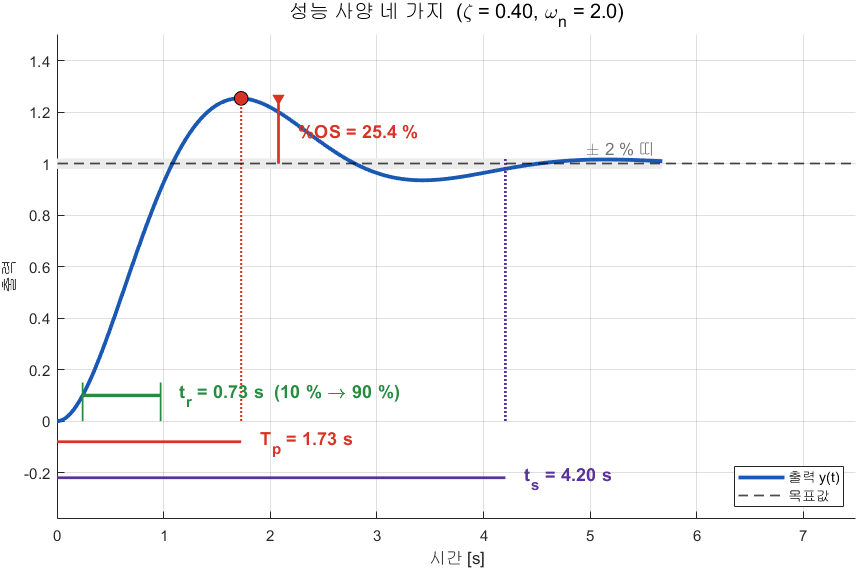

성능 사양 네 가지를 한 응답 위에 전부 표시했다

**그림 파일** `stepspec.png` — `common/dg_stepspec.m` 의 `dg_stepspec` · 다시 만들려면 `make_figures('stepspec')`

**만드는 곳** — `common/dg_stepspec.m` 을 `dg_stepspec(0.4, 2)` 로 부릅니다. 명령창에서 `dg_stepspec(0.7, 3)` 처럼 직접 불러도 됩니다 **직접 바꿔 보려면** — `W04_01_first_second_order.m` 의 **3절**에서 $\zeta$ 와 $\omega_n$ 을 바꾸면 네 숫자가 어떻게 움직이는지 표로 나옵니다

그림 해석 — **이 표를 그대로 읽으면 1절 설명이 됩니다**

네 숫자가 서로 다른 것을 재고 있다는 점을 보십시오. $t_r$ 과 $t_p$ 는 **얼마나 빠른가**, $\%OS$ 는 **얼마나 튀는가**, $t_s$ 는 **언제 끝나는가**입니다.

## 1-0. 네 숫자를 하나씩

- **상승시간** $t_r$ — 최종값의 $10\%$ 에서 $90\%$ 까지 걸린 시간. 얼마나 **빠른가**

- **오버슈트** $\%OS$ — 최댓값이 최종값을 넘어선 정도. 얼마나 **흔들리는가**

- **첨두시간** $t_p$ — 최댓값에 도달한 시각

- **정착시간** $t_s$ — 최종값의 $\pm2\%$ 안에 들어와 다시 벗어나지 않는 시각

이 중 **오버슈트와 정착시간**이 사양으로 가장 많이 쓰입니다.

- 오버슈트 — 넘어가면 부딪히거나 부서지는 문제 (로봇 팔, 엘리베이터)

- 정착시간 — 다음 작업을 언제 시작할 수 있는가 (반도체 스테이지, 프린터 헤드)

## 2. 1차 시스템 — 숫자 하나면 끝

표준형은 이것입니다.


$$G(s) = \frac{1}{\tau s + 1}$$


$\tau$ 를 **시정수**라 하며, 이 하나가 모든 것을 정합니다.

- 극점 — $s = -1/\tau$

- $63\%$ 도달 — $t = \tau$

- 상승시간 — 약 $2.2\tau$

- 정착시간 — 약 $4\tau$

**중요** — 1차 시스템은 절대로 오버슈트가 없습니다. 극점이 실수 하나뿐이라 **진동할 방법이 없기** 때문입니다.

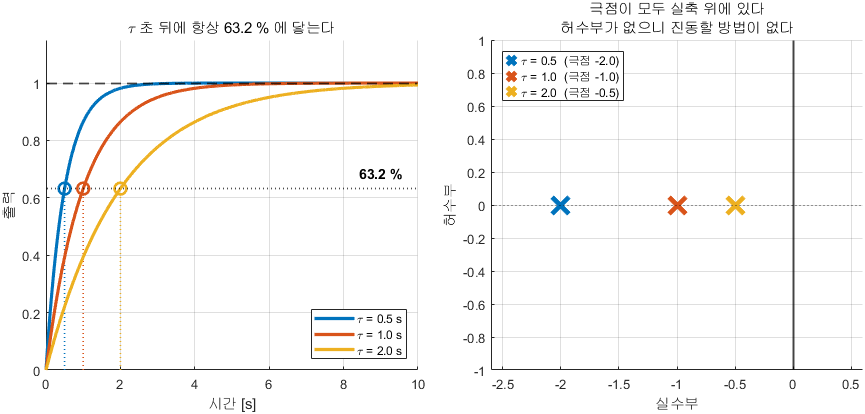

시정수 하나가 응답 전체를 정한다

**그림 파일** `w04_first_order.png` — `make_figures.m` 의 `fig_w04_first_order` · 다시 만들려면 `make_figures('w04_first_order')`

**만드는 곳** — `make_figures.m` 의 `fig_w04_first_order` **직접 바꿔 보려면** — `W04_01_first_second_order.m` 의 **2절**에서 `tau` 목록을 바꿔 실행

그림 해석

왼쪽과 오른쪽을 함께 읽으십시오. **극점이 왼쪽에 있을수록 빠르다** 가 오늘 계속 나올 문장이고, 여기가 그 첫 등장입니다.

t = 0:0.01:12;
for tau = [0.5 1 2]
    plot(t, step(1/(tau*s+1), t), 'LineWidth', 2); hold on
end
yline(1,'k--','LineWidth',1.5); yline(0.632,'r:','LineWidth',1.5)
grid on; xlabel('시간 [s]'); ylabel('출력')
title('1차 시스템 : 시정수가 전부다')
legend('\tau = 0.5','\tau = 1','\tau = 2','목표값','63.2 %','Location','southeast')

## 3. 2차 시스템 — 숫자 두 개

표준형입니다.


$$G(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


- $\omega_n$ **고유진동수** — 얼마나 빠른가

- $\zeta$ **감쇠비** — 얼마나 진동하는가

## 3-0. 이 표준형이 어디서 나왔는가

하늘에서 떨어진 식이 아닙니다. **2주차의 질량-스프링-댐퍼가 그대로 여기 있습니다.**

2주차에서 얻은 전달함수는 이랬습니다.


$$G(s) = \frac{1}{m s^2 + b s + k}$$


분모의 최고차항 계수를 $1$ 로 만들기 위해 **분자와 분모를 **$m$** 으로 나눕니다.**


$$G(s) = \frac{1/m}{s^2 + \frac{b}{m} s + \frac{k}{m}}$$


이제 두 계수에 이름을 붙입니다. 이름을 이렇게 붙이는 것이 표준형의 전부입니다.


$$\omega_n^2 \;\equiv\; \frac{k}{m}, \qquad 2\zeta\omega_n \;\equiv\; \frac{b}{m}$$


넣어서 정리하면


$$G(s) = \frac{1/m}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


마지막으로 **정상상태 이득이 **$1$** 이 되도록** 분자를 맞춥니다. $s=0$ 을 넣으면 $G(0) = \frac{1/m}{\omega_n^2} = \frac{1/m}{k/m} = \frac{1}{k}$ 이므로 분자에 $k/m = \omega_n^2$ 를 곱해 두면 $G(0)=1$ 이 됩니다.


$$G(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


**두 이름의 뜻도 이 유도에서 바로 나옵니다.**

$\zeta$ 의 식은 $2\zeta\omega_n = b/m$ 에 $\omega_n=\sqrt{k/m}$ 를 넣어 풀면 나옵니다.


$$\zeta = \frac{b}{2m\omega_n} = \frac{b}{2m\sqrt{k/m}} = \frac{b}{2\sqrt{km}}$$


## 3-0-1. 극점은 근의 공식으로 나온다

극점은 분모를 $0$ 으로 만드는 $s$ 입니다 (2주차).


$$s^2 + 2\zeta\omega_n s + \omega_n^2 = 0$$


**중학교 때 배운 근의 공식** $s = \frac{-B \pm \sqrt{B^2-4AC}}{2A}$ 를 그대로 씁니다. 여기서 $A=1$, $B = 2\zeta\omega_n$, $C = \omega_n^2$ 이므로


$$s = \frac{-2\zeta\omega_n \pm \sqrt{4\zeta^2\omega_n^2 - 4\omega_n^2}}{2}$$


근호 안에서 $4\omega_n^2$ 을 묶어냅니다.


$$\sqrt{4\omega_n^2(\zeta^2-1)} = 2\omega_n\sqrt{\zeta^2-1}$$


이것을 넣고 $2$ 로 약분하면


$$s = -\zeta\omega_n \pm \omega_n\sqrt{\zeta^2 - 1}$$


**여기서 **$\zeta < 1$** 인 경우가 우리가 볼 경우입니다.** 그러면 근호 안이 음수이므로 $\sqrt{\zeta^2-1} = j\sqrt{1-\zeta^2}$ 가 되어


$$s = -\zeta\omega_n \pm j\,\omega_n\sqrt{1-\zeta^2}$$


**근호 안의 부호 하나가 세 경우를 가릅니다.** 2주차에서 본 그 이야기입니다.

이 식을 뜯어보면 극점 위치의 의미가 그대로 보입니다.

- 실수부 $= -\zeta\omega_n$ — 얼마나 **빨리 사라지는가**

- 허수부 $= \omega_n\sqrt{1-\zeta^2}$ — 얼마나 **빨리 흔들리는가**

- 원점까지 거리 $= \omega_n$ — 멀수록 빠르다

- 실축과의 각도 $= \arccos\zeta$ — 클수록 많이 진동한다

**마지막 두 줄이 오늘 가장 중요합니다.** 극점을 극좌표로 읽으면 거리가 빠르기, 각도가 진동입니다.

## 3-1. 감쇠비를 바꿔 보면

$\omega_n$ 을 고정하고 $\zeta$ 만 바꿉니다. 왼쪽이 응답, 오른쪽이 그때의 극점 위치입니다.

극점 그림에서 확인할 것

- $\zeta$ 가 작으면 극점이 **허수축에 가깝다** (많이 진동)

- $\zeta = 1$ 이면 극점이 **실축 위에서 만난다** (진동 없음)

- $\zeta > 1$ 이면 실축을 따라 **좌우로 갈라진다**

- $\zeta < 1$ 인 동안 모든 극점이 **반지름 **$\omega_n$** 인 원 위**에 있다

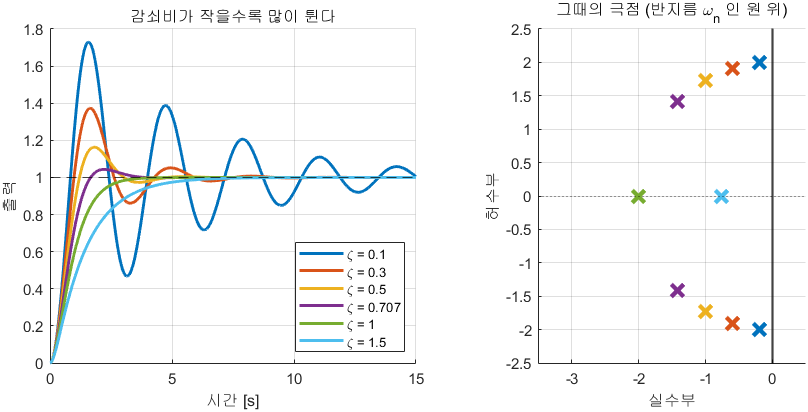

감쇠비와 극점 위치, 그리고 응답

**그림 파일** `w04_zeta_sweep.png` — `make_figures.m` 의 `fig_zeta_sweep` · 다시 만들려면 `make_figures('w04_zeta_sweep')`

**만드는 곳** — `make_figures.m` 의 `fig_zeta_sweep` **직접 바꿔 보려면** — `W04_01_first_second_order.m` 의 **3절**에서 `zl` 목록을 바꿔 실행

그림 해석

왼쪽 곡선 하나와 오른쪽 $\times$ 하나가 **짝**입니다. 색으로 짝을 찾아 보십시오.

wn = 2;  zl = [0.1 0.3 0.5 0.707 1.0 1.5];  t2 = 0:0.01:15;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
for z = zl
    plot(t2, step(wn^2/(s^2+2*z*wn*s+wn^2), t2), 'LineWidth', 2); hold on
end
yline(1,'k--','LineWidth',1.5); grid on
xlabel('시간 [s]'); ylabel('출력'); title('계단응답')
legend('\zeta=0.1','\zeta=0.3','\zeta=0.5','\zeta=0.707','\zeta=1.0','\zeta=1.5', ...
       'Location','southeast')
nexttile
for z = zl
    pl = pole(wn^2/(s^2+2*z*wn*s+wn^2));
    plot(real(pl), imag(pl), 'x', 'MarkerSize',12, 'LineWidth',3); hold on
end
xline(0,'k-','LineWidth',1.5); yline(0,'k:')
grid on; axis equal; xlim([-3.5 0.5]); ylim([-2.5 2.5])
xlabel('Real'); ylabel('Imag'); title('그때의 극점 위치')

## 3-2. 표로 읽기

위 그림을 숫자로 옮기면 이렇습니다.

- $\zeta = 0.1$ — 오버슈트 $73\%$. 심하게 흔들린다

- $\zeta = 0.5$ — 오버슈트 $16\%$. 쓸 만한 수준

- $\zeta = 0.707$ — 오버슈트 $4.3\%$. 흔히 **좋은 설계**로 치는 값

- $\zeta = 1.0$ — 오버슈트 $0\%$. 진동 없이 가장 빠름 (임계감쇠)

- $\zeta = 1.5$ — 오버슈트 $0\%$. 진동은 없지만 **오히려 느려짐** (과감쇠)

왜 $\zeta = 0.707$ 을 선호하는가

- 오버슈트가 $5\%$ 아래로 작으면서 정착시간이 짧다

- 주파수응답에서 **공진 피크가 사라지는 경계**이기도 하다 (10주차에서 다시 만남)

for z = zl
    info = stepinfo(wn^2/(s^2+2*z*wn*s+wn^2));
    fprintf('zeta = %.3f : 오버슈트 %5.1f %%, 상승시간 %.2f s, 정착시간 %5.2f s\n', ...
            z, info.Overshoot, info.RiseTime, info.SettlingTime);
end

## 4. 오늘의 핵심 — 사양과 극점을 잇는 두 공식

이 두 공식이 4주차의 전부이고, 6주차 설계의 출발점입니다.

## 4-1. 공식 하나 — 오버슈트는 감쇠비만으로 정해진다


$$\%OS = 100\,\exp\left(\frac{-\zeta\pi}{\sqrt{1-\zeta^2}}\right)$$


$\omega_n$** 이 전혀 없다는 점에 주목하십시오.** 오버슈트는 $\zeta$ 만의 함수입니다. 즉 시스템을 아무리 빠르게 만들어도 $\zeta$ 가 같으면 오버슈트는 똑같습니다.

이 식을 뒤집으면 설계용 공식이 됩니다.


$$\zeta = \frac{-\ln(\%OS/100)}{\sqrt{\pi^2 + \ln^2(\%OS/100)}}$$


**"**$\omega_n$** 이 없다"** 는 말이 잘 안 와닿을 것입니다. 오른쪽 그림에서 $\omega_n$ 을 네 배로 키워도 봉우리 높이가 **한 치도 안 변하는 것**을 보십시오.

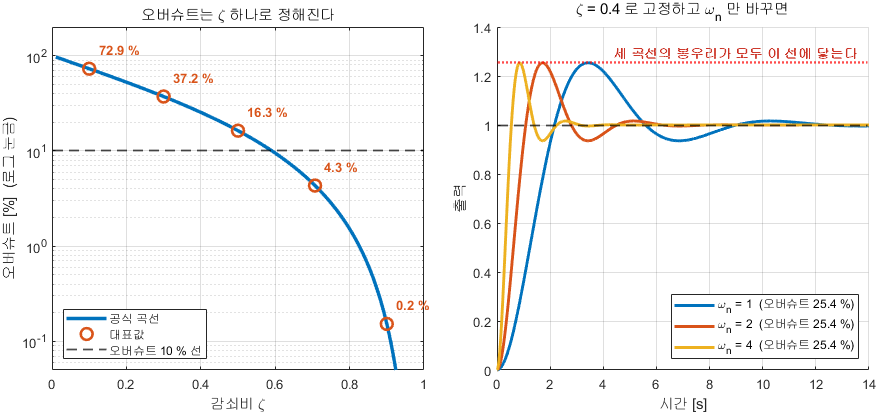

오버슈트는 오직 감쇠비만의 함수다

**그림 파일** `w04_os_zeta.png` — `make_figures.m` 의 `fig_w04_os_zeta` · 다시 만들려면 `make_figures('w04_os_zeta')`

**만드는 곳** — `make_figures.m` 의 `fig_w04_os_zeta` **직접 바꿔 보려면** — 명령창에 `100*exp(-0.5*pi/sqrt(1-0.5^2))` 를 쳐 보면 곡선의 한 점을 손으로 확인할 수 있습니다

그림 해석

## 4-1-1. 이 공식이 어디서 오는가 (유도)

외울 필요는 없지만 **한 번은 따라가 보십시오.** 세 줄이면 됩니다.

**1단계 — 계단응답을 적는다**

2차 표준형에 계단을 넣고 역라플라스 변환하면 이렇게 됩니다 (부족감쇠 $0 < \zeta < 1$ 인 경우).


$$y(t) = 1 - \frac{e^{-\zeta\omega_n t}}{\sqrt{1-\zeta^2}}\, \sin\left(\omega_d t + \phi\right), \qquad \omega_d = \omega_n\sqrt{1-\zeta^2}$$


여기서 $\phi = \arccos\zeta$ 입니다. 눈여겨볼 것은 $e^{-\zeta\omega_n t}$** 가 점점 작아지는 봉투** 라는 점입니다. 진동이 그 봉투 안에서 잦아듭니다.

**2단계 — 언제 가장 높은가**

$y(t)$ 를 미분해서 $0$ 이 되는 첫 시각을 찾으면


$$\frac{dy}{dt} = 0 \qquad \Rightarrow \qquad t = T_p = \frac{\pi}{\omega_d}$$


즉 **첨두시간은 진동 반주기**입니다. 한 번 올라갔다가 꼭대기에 닿는 시각입니다.

**3단계 — 그때 값이 얼마인가**

$t = T_p$ 를 1단계 식에 넣으면 $\sin$ 항이 정리되어


$$y(T_p) = 1 + e^{-\zeta\pi/\sqrt{1-\zeta^2}}$$


가 됩니다. 최종값이 $1$ 이므로 넘어선 몫은 뒤의 지수항뿐입니다.


$$\%OS = \frac{y(T_p) - 1}{1}\times 100 = 100\,e^{-\zeta\pi/\sqrt{1-\zeta^2}}$$


**왜 **$\omega_n$** 이 사라졌는가**

$\omega_n$ 은 지수의 어깨에 $\zeta\omega_n t$ 로 들어 있는데, $t = T_p = \pi/(\omega_n\sqrt{1-\zeta^2})$ 를 넣는 순간 $\omega_n$ 이 약분됩니다. **빠르기는 바뀌어도 모양은 안 바뀐다** 는 뜻입니다.

숫자로 확인해 봅니다.

fprintf('=== 유도한 공식이 맞는지 확인 ===\n');
fprintf('  zeta   %%OS(공식)   %%OS(실측)   Tp(공식)   Tp(실측)\n');
fprintf('  ----  ----------  ----------  ---------  ---------\n');
for z = [0.2 0.4 0.6 0.8]
    for w = 2
        Gx  = w^2/(s^2 + 2*z*w*s + w^2);
        ix  = stepinfo(Gx);
        os_f = 100*exp(-z*pi/sqrt(1-z^2));
        Tp_f = pi/(w*sqrt(1-z^2));
        fprintf('  %4.1f  %10.2f  %10.2f  %9.3f  %9.3f\n', ...
                z, os_f, ix.Overshoot, Tp_f, ix.PeakTime);
    end
end
fprintf('  --> 공식과 실측이 거의 같습니다\n\n');
% 봉투와 응답을 함께 그려 본다
z = 0.3; w = 2;
Gx = w^2/(s^2 + 2*z*w*s + w^2);
tx = (0:0.01:10)';
yx = step(Gx, tx);
env = exp(-z*w*tx)/sqrt(1-z^2);
plot(tx, yx, 'LineWidth', 2.5); hold on;
plot(tx, 1 + env, 'r--', 'LineWidth', 1.5);
plot(tx, 1 - env, 'r--', 'LineWidth', 1.5, 'HandleVisibility','off');
yline(1, 'k:'); grid on;
Tp = pi/(w*sqrt(1-z^2));
plot(Tp, 1 + exp(-z*pi/sqrt(1-z^2)), 'o', 'MarkerSize', 10, ...
     'MarkerFaceColor', 'm', 'MarkerEdgeColor', 'k');
xlabel('시간 [s]'); ylabel('출력');
legend('계단응답', '봉투 1 \pm e^{-\zeta\omega_n t}/\sqrt{1-\zeta^2}', ...
       '최종값', '첨두점 (공식으로 예측한 위치)', 'Location','northeast');
title('진동은 지수 봉투 안에서 잦아든다');

## 4-2. 공식 둘 — 정착시간은 실수부만으로 정해진다


$$t_s \approx \frac{4}{\zeta\omega_n}$$


분모 $\zeta\omega_n$ 이 바로 **극점 실수부의 크기**입니다.

- 응답의 포락선이 $e^{-\zeta\omega_n t}$ 로 줄어든다

- 이것이 $2\%$ 까지 줄어드는 시간이 $t_s$ 다

즉 정착시간 사양은 "극점이 얼마나 왼쪽에 있어야 하는가"를 정합니다.

**주의** — 이 식은 포락선만 보고 만든 **근사식**입니다. 실제 정착시간은 이보다 짧게 나오는 경우가 많은데, 안전한 쪽으로 틀리므로 설계에 쓰기 좋습니다.

이번에는 반대로 $\zeta$** 를 고정하고 실수부만** 바꿔 봅니다.

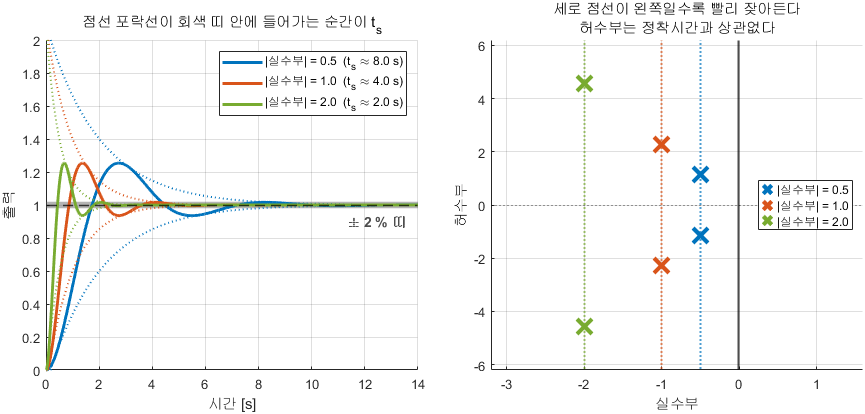

정착시간은 극점의 실수부 하나로 정해진다

**그림 파일** `w04_ts_envelope.png` — `make_figures.m` 의 `fig_w04_ts_envelope` · 다시 만들려면 `make_figures('w04_ts_envelope')`

**만드는 곳** — `make_figures.m` 의 `fig_w04_ts_envelope` **직접 바꿔 보려면** — `W04_01_first_second_order.m` 의 **3절**에서 $\omega_n$ 을 바꾸면 `stepinfo` 의 `SettlingTime` 이 따라 움직입니다

그림 해석

4-1 절과 이 절을 합치면 오늘의 두 문장이 완성됩니다.

- **각도가 오버슈트를 정한다** ($\zeta = \cos\theta$)

- **실수부가 정착시간을 정한다** ($t_s \approx 4/|\sigma|$)

## 4-3. 두 공식을 함수로

이 과목에서는 `spec2pole` 함수로 만들어 두었습니다. 6, 7, 13주차에서 계속 씁니다.

- **입력** — 허용 오버슈트 $[\%]$, 허용 정착시간 $[\mathrm{s}]$

- **출력** — 필요한 $\zeta$ 최솟값, 필요한 $\omega_n$ 최솟값, 목표 극점

아래에서 요구를 넣고 확인해 봅니다.

P_OS = 10;  ts = 2;
[zeta_min, wn_min, s_target] = spec2pole(P_OS, ts);
fprintf('요구 : 오버슈트 %.0f %% 이하, 정착시간 %.1f s 이하\n', P_OS, ts);
fprintf('필요 : zeta >= %.4f,  wn >= %.4f rad/s\n', zeta_min, wn_min);
fprintf('목표 극점 : %.3f +- %.3fj  (실축과 %.1f 도)\n', ...
        real(s_target), imag(s_target), rad2deg(acos(zeta_min)));
info_t = stepinfo(wn_min^2/(s^2+2*zeta_min*wn_min*s+wn_min^2));
fprintf('확인 : 실제 오버슈트 %.2f %%, 실제 정착시간 %.2f s\n', ...
        info_t.Overshoot, info_t.SettlingTime);

## 5. 사양을 $s$ 평면의 영역으로 그리기

이제 한 걸음 더 나갑니다. 두 조건을 **그림**으로 그립니다.

왜 그리는가

- 제어기 설계란 결국 **극점을 어디에 놓을 것인가**를 정하는 일이다

- 사양을 영역으로 그려 두면 **이 안에만 들어오면 합격**이 된다

- 설계가 눈으로 하는 작업이 된다

- 6주차에서 이 영역 위에 근궤적을 겹쳐 그린다

결과부터 보여 드리겠습니다. 아래 초록색 영역이 "합격" 구역입니다.

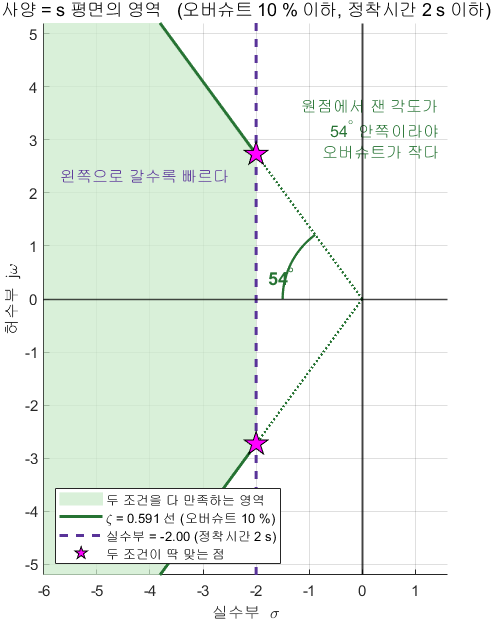

사양의 합격 영역 (오버슈트 10 %, 정착시간 2 s)

**그림 파일** `region_10_2.png` — `common/dg_region.m` 의 `dg_region` · 다시 만들려면 `make_figures('region_10_2')`

**만드는 곳** — `common/dg_region.m` 을 `dg_region(10, 2)` 로 부릅니다. 명령창에서 `dg_region(5, 1)` 처럼 다른 사양으로 직접 불러도 됩니다 **직접 바꿔 보려면** — `W04_02_spec_region.m` 을 실행하면 사양을 바꿔 가며 영역이 어떻게 좁아지는지 볼 수 있습니다

그림 해석

이 그림에서 읽을 것 세 가지

- **세로 점선** — 정착시간 조건. 이 선보다 **왼쪽**이라야 충분히 빠르다

- **비스듬한 실선** — 오버슈트 조건. 이 안쪽이라야 충분히 덜 흔들린다

- **별표** — 두 조건이 딱 맞아떨어지는 점. 여기가 목표 극점이다

아래에서 이 두 경계가 왜 그렇게 생겼는지 하나씩 봅니다.

## 5-1. 오버슈트 조건은 부채꼴

오버슈트는 $\zeta$ 만으로 정해지고, $\zeta$ 는 **각도**로 나타납니다.

- $\zeta \ge \zeta_{\min}$ 이라는 조건은

- 실축과의 각도가 $\arccos \zeta_{\min}$ 이하라는 뜻과 같다

따라서 오버슈트 조건은 **원점을 꼭짓점으로 하는 부채꼴 안쪽**입니다. 부채꼴이 좁을수록 덜 진동합니다.

- 오버슈트 $5\%$ — $\zeta \ge 0.690$ — 각도 $\le 46.4^\circ$

- 오버슈트 $10\%$ — $\zeta \ge 0.591$ — 각도 $\le 53.8^\circ$

- 오버슈트 $20\%$ — $\zeta \ge 0.456$ — 각도 $\le 62.9^\circ$

- 오버슈트 $40\%$ — $\zeta \ge 0.280$ — 각도 $\le 73.7^\circ$

r = linspace(0,6,100);
for os = [5 10 20 40]
    zmin = spec2pole(os, 1);  th = acos(zmin);
    plot(-r*cos(th), r*sin(th), 'LineWidth', 2); hold on
    plot(-r*cos(th), -r*sin(th), 'LineWidth', 2, 'HandleVisibility','off')
end
xline(0,'k-','LineWidth',1.5); yline(0,'k:')
grid on; axis equal; xlim([-6 1]); ylim([-5 5])
xlabel('Real'); ylabel('Imag')
title('오버슈트 조건 : 이 직선보다 실축 쪽이어야 한다')
legend('5 % 한계','10 % 한계','20 % 한계','40 % 한계','Location','southwest')

## 5-2. 정착시간 조건은 수직선

정착시간은 실수부만으로 정해지므로


$$|\text{실수부}| \ge \frac{4}{t_s}$$


즉 **어떤 수직선보다 왼쪽**이어야 합니다. 빠른 응답을 원할수록 이 수직선이 왼쪽으로 밀려납니다.

- $t_s = 1\,\mathrm{s}$ — 실수부 $\le -4$

- $t_s = 2\,\mathrm{s}$ — 실수부 $\le -2$

- $t_s = 4\,\mathrm{s}$ — 실수부 $\le -1$

## 5-3. 두 조건을 합치면

부채꼴과 수직선을 동시에 만족하는 영역은 **왼쪽으로 열린 쐐기 모양**입니다. 이 안에 지배극점이 들어오면 사양을 만족합니다.

5-1, 5-2, 5-3 을 한 줄에 놓고 보면 영역이 어떻게 쌓이는지 분명해집니다.

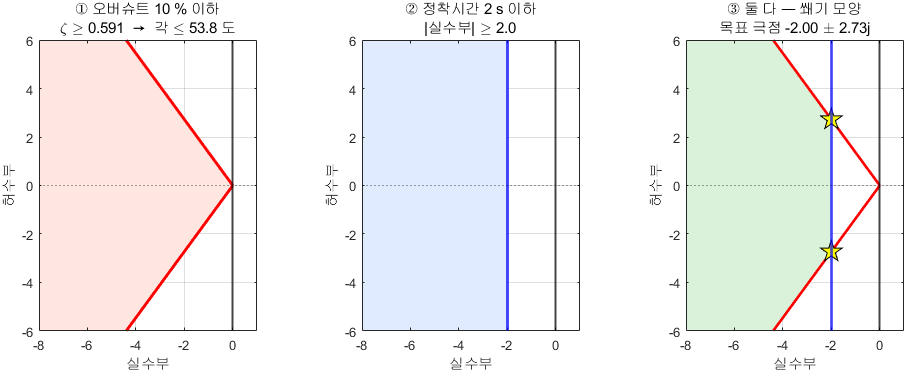

부채꼴 + 수직선 = 쐐기

**그림 파일** `w04_region_build.png` — `make_figures.m` 의 `fig_w04_region_build` · 다시 만들려면 `make_figures('w04_region_build')`

**만드는 곳** — `make_figures.m` 의 `fig_w04_region_build` **직접 바꿔 보려면** — 함수 안의 `P_OS = 10; ts = 2;` 를 바꾸면 세 그림이 함께 움직입니다

그림 해석

①과 ②를 따로 보면 각각 **모자랍니다.** 둘을 겹쳐야 비로소 쓸 만한 영역이 나온다는 것이 5절의 요지입니다.

MATLAB 에는 이 영역을 그려 주는 명령이 있습니다.

- `sgrid(zeta, wn)` — 등감쇠비 직선과 등고유진동수 원을 그린다

- $\omega_n$ 을 원으로 그리므로 수직선 조건과는 조금 다르지만, 원이 수직선보다 보수적이라 실용상 문제가 없다

- 6주차부터 계속 쓴다

P_OS = 10; ts = 2;
[zeta_min, wn_min, s_t] = spec2pole(P_OS, ts);
th = acos(zeta_min);
xv = linspace(-8, -4/ts, 200);  yv = -xv*tan(th);
fill([xv fliplr(xv)], [yv -fliplr(yv)], [0.85 0.95 0.85], 'EdgeColor','none'); hold on
rr = linspace(0,9,100);
plot(-rr*cos(th), rr*sin(th), 'r-', 'LineWidth', 2)
plot(-rr*cos(th), -rr*sin(th), 'r-', 'LineWidth', 2, 'HandleVisibility','off')
xline(-4/ts, 'b-', 'LineWidth', 2)
plot(real(s_t), imag(s_t), 'kp', 'MarkerSize',16, 'MarkerFaceColor','y')
plot(real(s_t), -imag(s_t), 'kp', 'MarkerSize',16, 'MarkerFaceColor','y', ...
     'HandleVisibility','off')
xline(0,'k-','LineWidth',1.5); yline(0,'k:')
grid on; axis equal; xlim([-8 1]); ylim([-6 6])
xlabel('Real'); ylabel('Imag')
title('사양 영역 : 오버슈트 10 % 이하, 정착시간 2 s 이하')
legend('만족 영역','오버슈트 경계','정착시간 경계','목표 극점','Location','southwest')

## 5-4. 영역이 맞는지 확인

영역 안의 점과 밖의 점을 골라 실제 응답을 확인합니다. 안이면 합격, 밖이면 불합격이 나와야 합니다.

cand = {-2.0+2.7j,'영역 안 (경계)'; -3.0+2.0j,'영역 안 (여유)';
        -1.0+2.0j,'영역 밖 (느림)'; -2.0+5.0j,'영역 밖 (진동)'};
for i = 1:4
    p = cand{i,1};
    Gc = abs(p)^2/(s^2 - 2*real(p)*s + abs(p)^2);
    inf_c = stepinfo(Gc);
    if inf_c.Overshoot <= P_OS+0.5 && inf_c.SettlingTime <= ts+0.05
        mk = '합격'; else, mk = '불합격'; end
    fprintf('%+.1f%+.1fj  %-16s 오버슈트 %5.1f %%, 정착시간 %.2f s -> %s\n', ...
            real(p), imag(p), cand{i,2}, inf_c.Overshoot, inf_c.SettlingTime, mk);
end

## 6. 공식의 한계 — 극점이 셋 이상이면

두 공식은 **극점 두 개, 영점 없음**이라는 가정에서 나왔습니다. 현실의 시스템은 대개 그렇지 않습니다.

그래도 공식을 쓰는 이유

- 설계에는 **출발점**이 필요하다

- 공식으로 대략의 위치를 잡고, `stepinfo` 로 확인한 뒤 조정한다

아래에서 극점 하나를 더 붙여 봅니다. 기준 극점의 실수부는 $-2$ 입니다.

- 먼 극점 $s=-10$ (5배 멀다) — 거의 영향 없음

- 가까운 극점 $s=-1$ (절반) — 정착시간이 $2.4$ 배로 늘어남

**경험칙** — 다른 극점이 지배극점보다 **5배 이상 왼쪽**에 있으면 무시해도 됩니다. 가장 늦게 사라지는 극점을 **지배극점**이라 하고, 이것이 응답의 꼬리를 정합니다.

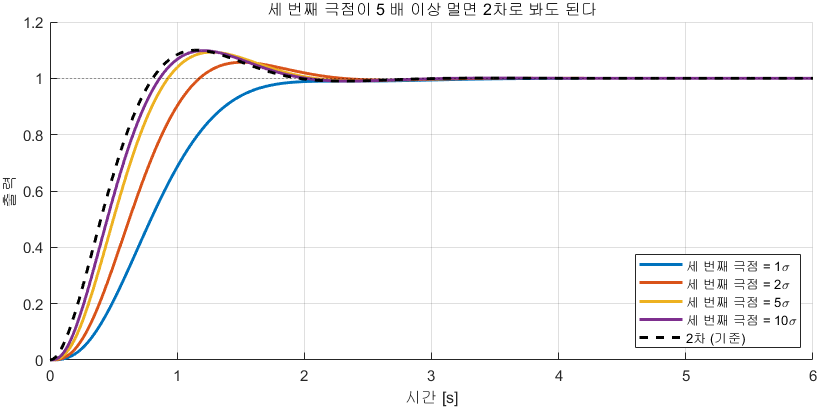

세 번째 극점이 5 배 이상 멀면 2차로 봐도 된다

**그림 파일** `w04_third_pole.png` — `make_figures.m` 의 `fig_third_pole` · 다시 만들려면 `make_figures('w04_third_pole')`

**만드는 곳** — `make_figures.m` 의 `fig_third_pole` **직접 바꿔 보려면** — 아래 코드에서 `Gt*(1/(s+1))` 의 `1` 을 `0.5`, `3`, `20` 으로 바꿔 실행

그림 해석

여기서 배울 실무 규칙 — **가장 오른쪽 극점(원점에 가장 가까운 것)이 응답을 지배합니다.** 이것을 **지배극점**이라 부르고, 6주차 근궤적 설계에서 계속 씁니다.

Gt = wn_min^2/(s^2+2*zeta_min*wn_min*s+wn_min^2);
t4 = 0:0.01:8;
plot(t4, step(Gt, t4), 'LineWidth', 2.5); hold on
plot(t4, step(Gt*(10/(s+10)), t4), '--', 'LineWidth', 2)
plot(t4, step(Gt*(1/(s+1)), t4), ':', 'LineWidth', 2.5)
yline(1,'k--'); grid on
xlabel('시간 [s]'); ylabel('출력')
title('극점을 하나 더 붙였을 때')
legend('2차 (기준)','먼 극점 s = -10','가까운 극점 s = -1','Location','southeast')

## 7. Simulink 로 확인하기

모델 `W04_SecondOrder_Sweep.slx` 는 표준 2차 시스템을 **적분기 두 개**로 구현한 것입니다. 전달함수 블록을 쓰지 않은 이유가 있습니다.


$$\ddot{y} = \omega_n^2 (r - y) - 2\zeta\omega_n \dot{y}$$


이 식을 그대로 블록으로 옮기면, **감쇠 경로의 게인 **$2\zeta\omega_n$ 이 $\zeta$ 가 들어가는 유일한 자리가 됩니다. 눈으로 보입니다.

확인할 것

- 그 게인을 $0$ 으로 하면 $\zeta = 0$ 이 되어 영원히 진동한다

- 즉 **감쇠란 속도를 되먹이는 일**이다

- 이것이 7주차 미분제어 D 의 원리와 정확히 같다

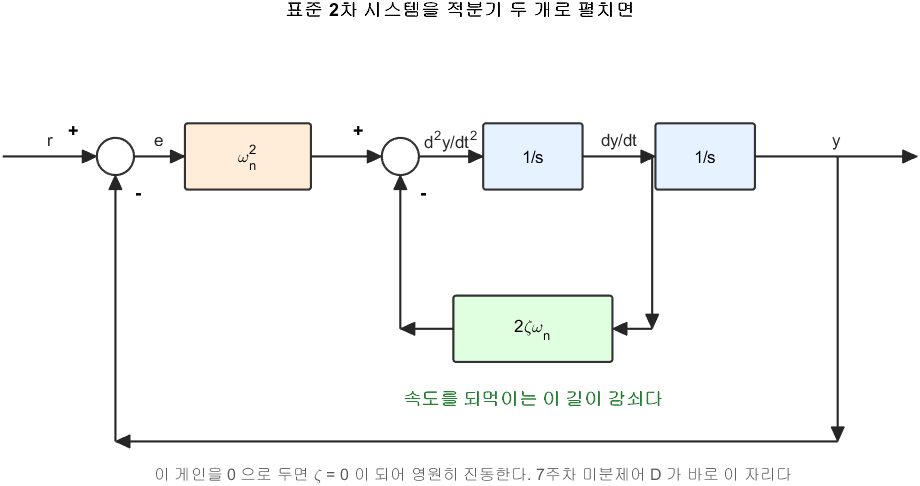

적분기 두 개로 펼치면 zeta 가 어디 있는지 보인다

**그림 파일** `w04_sim_blocks.png` — `common/dg_second_order.m` 의 `dg_second_order` · 다시 만들려면 `make_figures('w04_sim_blocks')`

**만드는 곳** — `common/dg_second_order.m` (`make_figures('w04_sim_blocks')`) **직접 확인해 보려면** — `W04_SecondOrder_Sweep.slx` 를 열면 **이 그림과 똑같은 블록 배치**가 그대로 있습니다

그림 해석

**초록 상자 하나가 감쇠의 전부입니다.** 이 게인을 $0$ 으로 두면 브레이크가 없어져 영원히 진동합니다. 7주차에서 배울 미분제어 $D$ 가 정확히 이 자리에 들어갑니다.

모델은 모델을 열고 `Ctrl+T` 로 실행해도 됩니다.

## 7-1. 스크립트에서 Simulink 를 반복 실행하기

이번 주에 새로 배우는 기법입니다.

블록에 숫자 대신 변수 이름을 적어 두면 스크립트에서 값만 바꿔 가며 `sim` 을 여러 번 부를 수 있습니다.

for zeta = [0.1 0.3 0.5] out = sim(model); end

주의할 점

- `sim` 은 워크스페이스의 **현재 값**을 읽는다

- 가변스텝 솔버라 시간 간격이 매번 다르므로 비교하려면 `interp1` 이 필요하다

- 시간 벡터는 **열벡터**로 만들 것

## 7-2. `stepinfo` 의 또 다른 사용법

지금까지는 `stepinfo(G)` 처럼 전달함수를 넣었습니다. 그런데 Simulink 결과처럼 **데이터만 있을 때**도 쓸 수 있습니다.

- **입력** — `stepinfo(y, t, yfinal)`. `y` 는 출력 데이터, `t` 는 시간, `yfinal` 은 최종값

- **출력** — 전달함수를 넣었을 때와 같은 구조체

`yfinal` 을 직접 알려 줘야 하는 이유

- 데이터만 봐서는 언제 끝나는지 MATLAB 이 알 수 없다

- 잘못 주면 정착시간이 엉뚱하게 나온다

실험 데이터를 분석할 때 이 형태를 많이 씁니다.

## 7-3. `stepinfo` 를 여러 가지로 써 본다

4주차의 사양은 전부 `stepinfo` 하나로 잽니다. 그런데 **기준을 어떻게 잡느냐에 따라 값이 달라집니다.** 사양서에 적힌 기준과 코드의 기준이 다르면 합격·불합격이 뒤집힙니다.

**기본값을 반드시 기억하십시오.** 상승시간은 $10\sim90\%$, 정착시간은 $\pm2\%$ 입니다.

s = tf('s');
Gz = 4/(s^2 + 0.8*s + 4);
tt = (0:0.001:20)';
yy = step(Gz, tt);

iSys  = stepinfo(Gz);
iData = stepinfo(yy, tt);
i010  = stepinfo(Gz, 'RiseTimeLimits', [0 1]);
i05   = stepinfo(Gz, 'SettlingTimeThreshold', 0.05);

fprintf('시스템에서   : Tr %.3f s, Ts %.3f s, OS %.1f %%\n', ...
        iSys.RiseTime, iSys.SettlingTime, iSys.Overshoot);
fprintf('데이터에서   : Tr %.3f s, Ts %.3f s, OS %.1f %%\n', ...
        iData.RiseTime, iData.SettlingTime, iData.Overshoot);
fprintf('상승시간 기준: 10~90%% -> %.3f s,  0~100%% -> %.3f s\n', ...
        iSys.RiseTime, i010.RiseTime);
fprintf('정착시간 기준: 2%% -> %.3f s,  5%% -> %.3f s\n', ...
        iSys.SettlingTime, i05.SettlingTime);
fprintf('\n같은 응답인데 기준만 바꿔도 정착시간이 %.1f 배 차이 납니다.\n', ...
        iSys.SettlingTime / i05.SettlingTime);

## 8. 오늘의 정리

- 성능은 네 숫자로 요약한다. 그중 **오버슈트와 정착시간**이 사양으로 많이 쓰인다

- 1차 시스템은 $\tau$ 하나. 오버슈트는 항상 $0$

- 2차 시스템은 $\omega_n$ 과 $\zeta$ 두 개

- 극점을 극좌표로 읽어라 — **거리가 빠르기, 각도가 진동**

- 오버슈트는 $\zeta$ 만의 함수다. $\omega_n$ 과 무관하다

- 정착시간은 극점 실수부만의 함수다

- 사양은 $s$ 평면의 **쐐기 모양 영역**이 된다. 지배극점이 그 안에 들어오면 합격

- 이 공식들은 2차 근사다. 반드시 `stepinfo` 로 확인할 것

## 9. 다음 주 예고

5주차에서는 두 가지를 합니다.

- **안정도** — 이득 $K$ 를 얼마까지 키울 수 있는가. 1주차에서 "무한히 키우면 안 된다" 고만 했던 것의 정확한 답

- **정상상태 오차** — 오차가 왜 남는지, 어떻게 없애는지. 시스템 타입과 오차상수라는 개념이 나옵니다

그리고 오늘 배운 "사양 영역" 위에 6주차에서 근궤적을 겹쳐 그리면 **제어기 설계**가 완성됩니다. 거기까지 두 주 남았습니다.